clear all
close all

%Grid parameters
Nx=200;
Ny=250;
Nz=320;

Lx=3000;%m
Ly=1500;%m
Lz=1000;%m

x=linspace(0,Lx,Nx);
y=linspace(-Ly/2,Ly/2,Ny);
z=linspace(0,Lz,Nz);


%Wake model parameters 
x_array  = zeros(Nx,1);
y_array  = zeros(Ny,1);
xo_array = zeros(1,1);
sigma2_x = zeros(Nx,1);
du_mag_x = zeros(Nx,1);
du0_mag_x= zeros(Nx,1);
Xe_w_a   = zeros(1,1);
kw_model = zeros(1,1);

kw_z_model       = zeros(Nz,1);
t_hat_xz         = zeros(Nx,Nz);
yc_majid_xz      = zeros(Nx,Nz);
yc_CVP_majid_xz  = zeros(Nx,Nz);
yc_g_majid_xz    = zeros(Nx,Nz);
theta_angle = zeros(Nx,Ny,Nz);
xi_dim      = zeros(Nx,Ny,Nz);
xi0_theta   = zeros(Nx,Ny,Nz);
sigma_width = zeros(Nx,Ny,Nz);
sigma_width_Gaussian = zeros(Nx,Ny,Nz);
yc_Veer     = zeros(Nx,Nz);

X_root=0;

%Turbine parameters
D=100;%m Diameter of wind turbine
Radius=D/2;
Ct_prime=1.33;
yaw_angle=20*pi/180;
zt=100%m hub height

zt = 100



%Sample ABL inflow parameters
utau_value=1;
z0=0.1;%m (surface roughness)
kappa=0.41;%Von-Karman constant
U_profile=utau_value/kappa*log(z/z0);%Sample wind profile

use_veer=0;
V_profile=-0.01*(z-zt)*use_veer;%Veer velocity profile
height_ABL=1000;%m


%Model constants for Turbulence Intensity
A1_const=-0.25;%Townsend-Perry constant
B1_const=0.6;



%Find location and index of hub height
[zt_val,zt_loc]=min(abs(z-zt));
z(zt_loc);
U_hub=U_profile(zt_loc);%Hub height velocity

**Compute **$C_T, a, A_*, \tilde{\xi}_0=R\sqrt{A_*}

$


$$C_T=\frac{16 C_T^\prime}{(4+C_T^\prime cos^2\beta)^2}$$



$$A_*=\frac{1+\sqrt{1-C_T\cos^2\beta}}{2\sqrt{1-C_T \cos^2\beta}}$$


Ct=16*Ct_prime/(4+Ct_prime*(cos(yaw_angle))^2)^2;
a_ind = 0.5*(1 - sqrt(1-Ct*(cos(yaw_angle))^2))

a_ind = 0.2270

A_star=(1+sqrt(1-Ct*(cos(yaw_angle))^2))/(2*sqrt(1-Ct*(cos(yaw_angle))^2));
xi0_tilde=Radius*sqrt(A_star);

**Maximum velocity deficit function: **$C(x)=\Delta u_{max}/U_h$ 


$$ C(x)=
\begin{cases}
2a & x\leq x_0,\\
1-\sqrt{1-\frac{C_T\cos^3\beta}{2\tilde{\sigma}^2(x)/R^2}}    & x\geq x_0
\end{cases}.$$



$$\tilde{\sigma}^2(x)=(k_w  x+0.4 R\sqrt{A_*})(k_w  x+0.4 R\sqrt{A_*}\cos\beta)$$


$x_0$** is transition location from potential core region to the region where velocity deficit decays downstream the wind turbine**


$$x_0 = \frac{1}{5 k_w} \Biggl(\sqrt{R^2 A_*(1-\cos\beta)^2 +25 \frac{R^2}{2}\frac{C_T\cos^3\beta}{(1-(1-2a)^2)}}
+R\sqrt{A_*} (1-\cos \beta)\Biggr)-\frac{2}{5k_w}R\sqrt{A_*}$$
 

[Cx,A_star,xo,kw]= Cx_func(yaw_angle,Ct,Radius, ...
                               utau_value, ...
                               U_hub,zt, ...
                               height_ABL, ...
                               x, ...
                               A1_const, ...
                               B1_const);


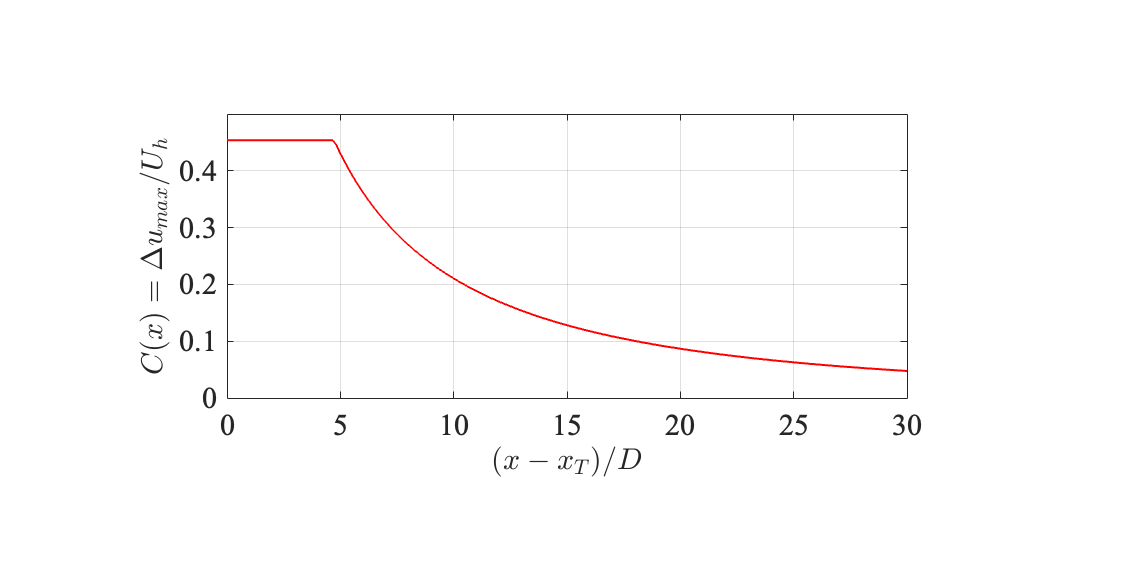

%Plot and check Cx
set(groot, 'DefaultFigureVisible', 'on');
close all
figure
set(gcf,'Color','w','Units','Centimeters','Position',[10 10 20 10]);
ax=axes;
ax.Units='Centimeters';
plot(x/D,Cx,'LineWidth',1,'Color','r');
set(gca,'fontsize',15,'fontname','Times');
xlabel('$(x-x_T)/D$','Interpreter','latex','FontSize',15);
ylabel('$C(x)=\Delta u_{max}/U_h$','Interpreter','latex','FontSize',15);
ylim([0 0.5])
grid on
ax.Position=[4 3 12 5];


$$ \hat{t}(x,z)\approx-1.44\frac{U_h}{u_*}\frac{R}{R\sqrt{A_*}}C_T\cos^2\beta\sin\beta 
 \,\, \left[1-\exp\left(-0.35\frac{u_*}{U(z)}\frac{x}{R}\right)\right]$$


t_hat_xz(:,:)  = t_hat_xz_func(yaw_angle,Ct,Radius,A_star, ...
                                          utau_value, ...
                                          U_hub,zt, ...
                                          height_ABL, ...
                                          x,z,...
                                          U_profile,...
                                          V_profile);
max(t_hat_xz(:)),min(t_hat_xz(:))

ans = 0

ans = -4.4945

**Wake displacement**


$$y_c(x,z)=\hat{y}_c(\hat{t})R\sqrt{A_*}+y_{c,\text{veer}}$$



$$\hat{y}_c(\hat{t})=\frac{(\pi-1)|\hat{t}|^3+2\sqrt{3}\pi^2\hat{t}^2+48(\pi-1)^2|\hat{t}|}{2\pi(\pi-1)\hat{t}^2+4\sqrt{3}\pi^2|\hat{t}|+96(\pi-1)^2}\text{sgn}(\hat{t}) -\frac{2}{\pi}\frac{\hat{t}}{[(z+z_h)/R\sqrt{A_*}]^2-1}$$


[yc_majid_xz(:,:),yc_CVP_majid_xz(:,:),yc_g_majid_xz(:,:)] = yc_func(t_hat_xz(:,:), ...
                                                                     Radius,A_star,zt, ...
                                                                     x,z);
for i=1:Nx
    for k=1:Nz
        yc_Veer(i,k)=x(i)*V_profile(k)/U_profile(k);
    end
end

[max(yc_majid_xz(:)),min(yc_majid_xz(:))]

ans =          0  -81.7707


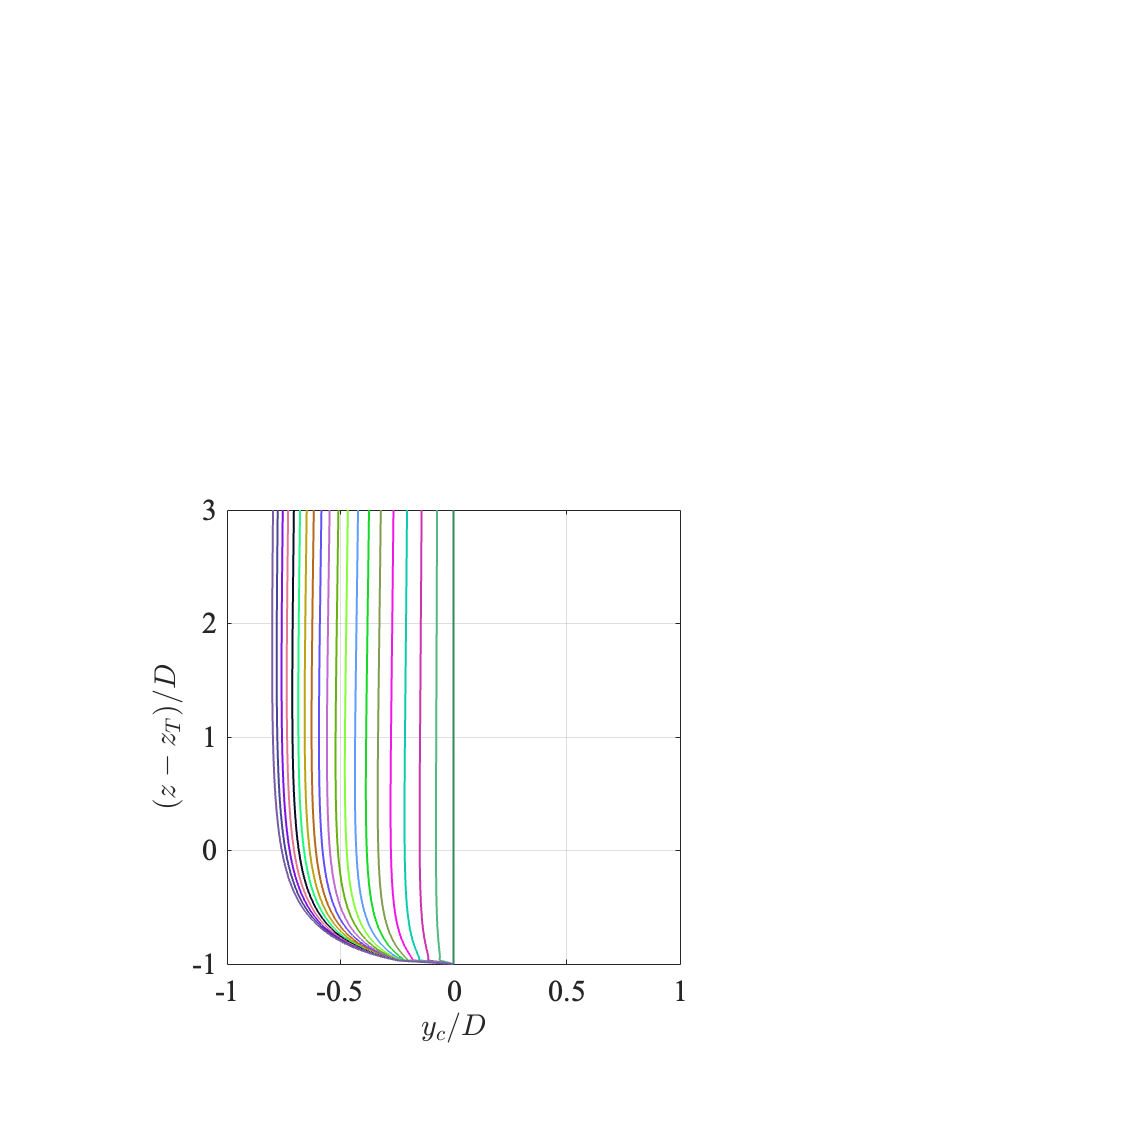

%Plot yc_majid_xz
set(groot, 'DefaultFigureVisible', 'on');
close all
figure
set(gcf,'Color','w','Units','Centimeters','Position',[10 10 20 20]);
ax=axes;
ax.Units='Centimeters';
for i=1:10:Nx
    plot(yc_majid_xz(i,:)/D,(z-zt)/D,'LineWidth',1,'Color',rand(1,3));hold on
end
xlim([-1 1])
ylim([-1 3])
set(gca,'fontsize',15,'fontname','Times');
xlabel('$y_c/D$','Interpreter','latex','FontSize',15);
ylabel('$(z-z_T)/D$','Interpreter','latex','FontSize',15);
grid on
ax.Position=[4 3 8 8];

**Polar angle**


$$  \theta=\tan^{-1}\left(\frac{z-z_h}{y-\hat{y}_c(\hat{t})R\sqrt{A_*}}\right)$$


theta_angle(:,:,:) = theta_func(x,y,z,zt,yc_majid_xz(:,:));

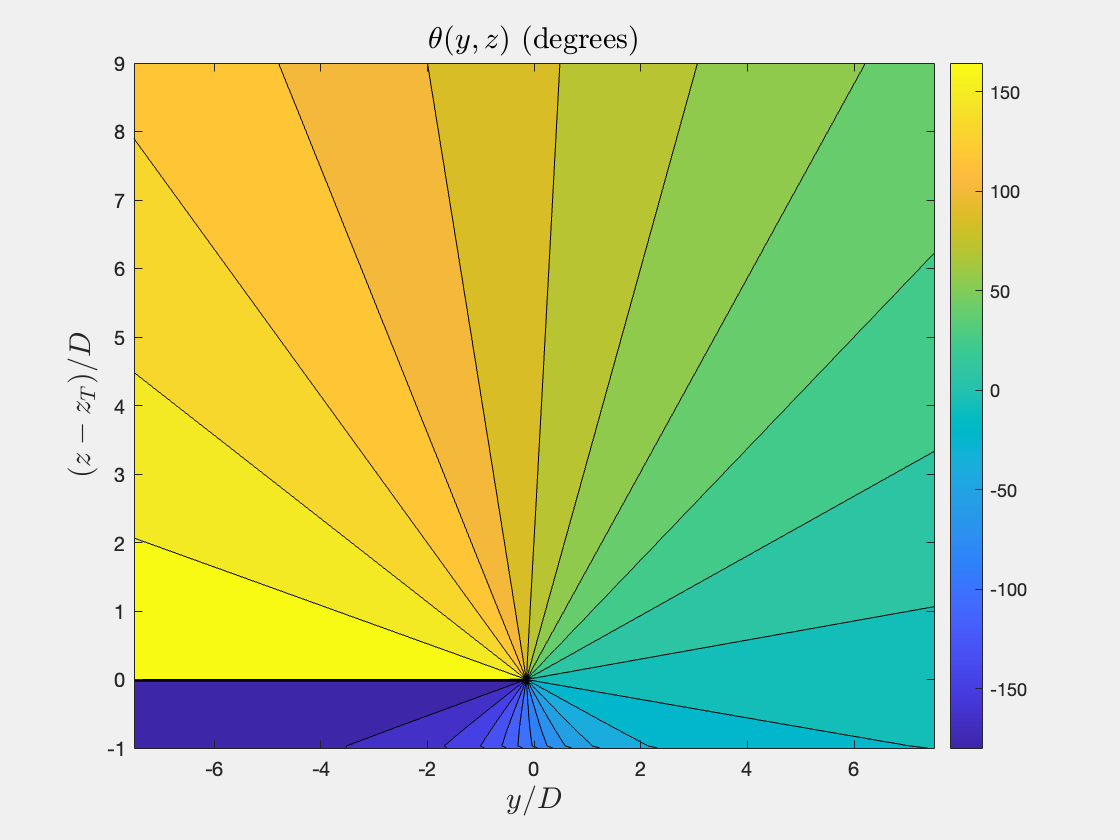

%Visualize theta_angle at specific streamwise location
xloc=20;
set(groot, 'DefaultFigureVisible', 'on');
close all
figure
contourf(y/D,(z-zt)/D,squeeze(theta_angle(xloc,:,:))'*180/pi,22)
xlabel('$y/D$','interpreter','latex','fontsize',15);
ylabel('$(z-z_T)/D$','interpreter','latex','fontsize',15);
title('$\theta(y,z)$ (degrees)','Interpreter','latex','fontsize',15);
colorbar

**Wake shape function:** $\xi(\theta,x) =  \xi_0(\theta) \, \hat{\xi}(\theta,\hat{t})$

**Initial wake shape:** $\xi_0(\theta)=R\sqrt{A_*}\frac{|\cos\beta|}{\sqrt{1-\sin^2\beta\sin^2\theta}}$

**Dimensionless wake shape function:** $\hat{\xi}(\theta,\hat{t})=1-\alpha\biggl[
\frac{1}{2}\tanh\left(\frac{\hat{t}^{2}}{4\alpha}\right)\cos2\theta
-\frac{1}{4}\tanh\left(\frac{\hat{t}^{3}}{8\alpha}\right)\cos(3\theta)
-\frac{5}{48}\tanh\left(\frac{\hat{t}^{4}}{16\alpha}\right)\cos(2\theta)
+\frac{7}{48}\tanh\left(\frac{\hat{t}^{4}}{16\alpha}\right)\cos(4\theta)  \biggr], \ \alpha=1.263$

[xi_dim(:,:,:), xi0_theta(:,:,:)] = wake_shape_func(yaw_angle,A_star,Radius,...
                                                    x,y,z, ...
                                                    theta_angle(:,:,:),...
                                                    t_hat_xz(:,:));

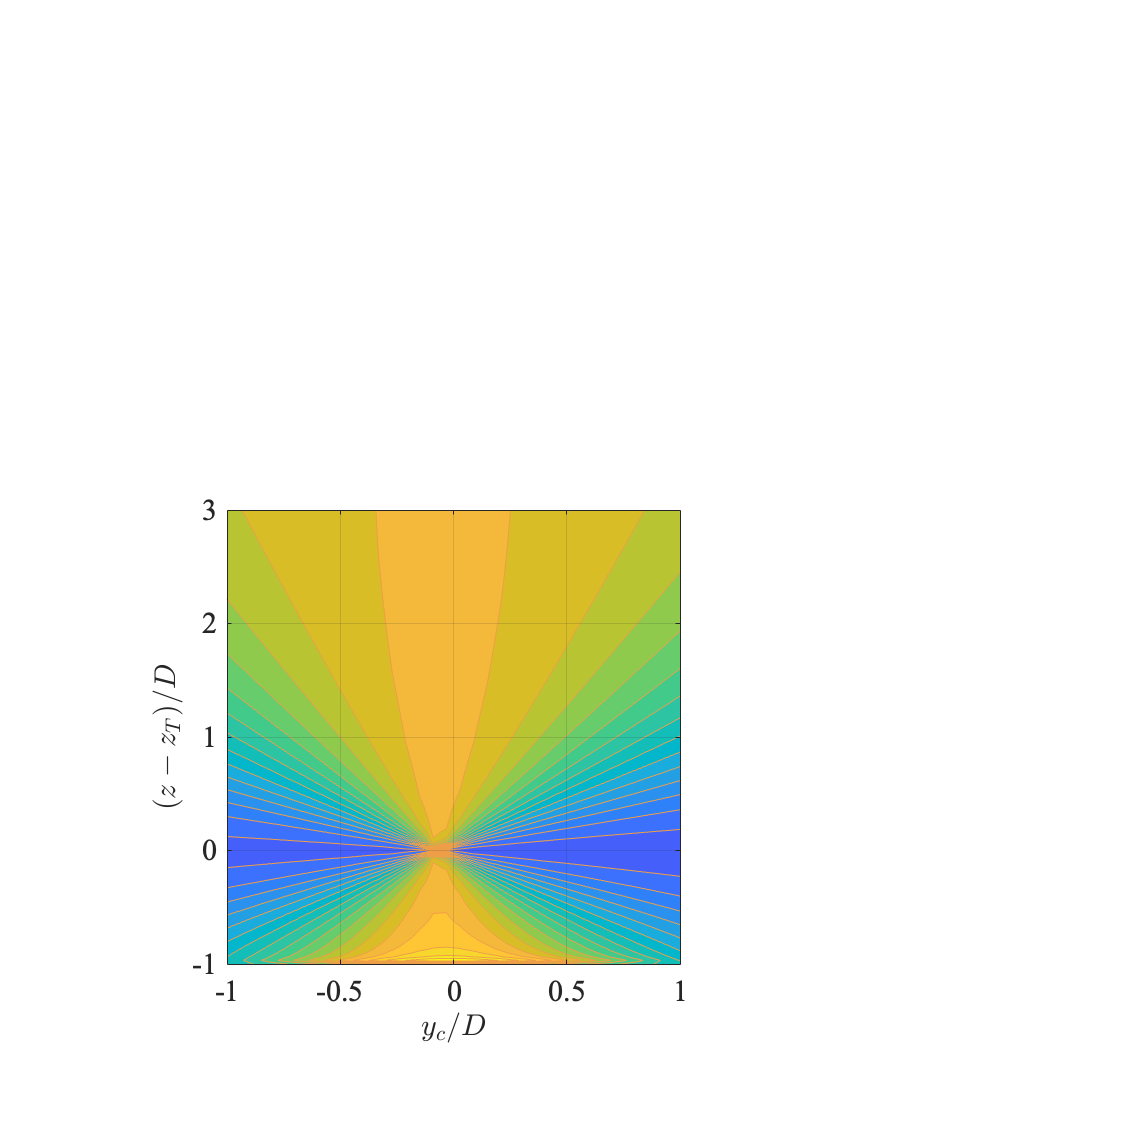

%Plot  wake shape function
set(groot, 'DefaultFigureVisible', 'on');
close all
figure
set(gcf,'Color','w','Units','Centimeters','Position',[10 10 20 20]);
ax=axes;
ax.Units='Centimeters';
for i=10:10%:Nx
    contourf(y/D,(z-zt)/D,squeeze(xi_dim(i,:,:))',22,'Color',rand(1,3));hold on
end
xlim([-1 1])
ylim([-1 3])
set(gca,'fontsize',15,'fontname','Times');
xlabel('$y_c/D$','Interpreter','latex','FontSize',15);
ylabel('$(z-z_T)/D$','Interpreter','latex','FontSize',15);
grid on
ax.Position=[4 3 8 8];

**Wake width:** $\sigma(\theta,x) = k_w \, x + 0.4 \, \xi(\theta,x)$

for i=1:Nx
    for j=1:Ny
        for k=1:Nz
            sigma_width(i,j,k) = kw*x(i)+0.4*xi_dim(i,j,k);       
        end
    end
end

**Velocity deficit**


$$\frac{\Delta u}{U_h} = C(x) \exp\left[-\frac{(y-y_c)^2+(z-z_h)^2}{2\ \sigma(\theta, x)^2}\right]$$


du_model = zeros(Nx,Ny,Nz);
for i=1:Nx
    for j=1:Ny
        for k=1:Nz
            du_model(i,j,k) = Cx(i).*exp(-((y(j)-yc_majid_xz(i,k)-yc_Veer(i,k)).^2+(z(k)-zt).^2)./(2*sigma_width(i,j,k)^2));
        end
    end
end

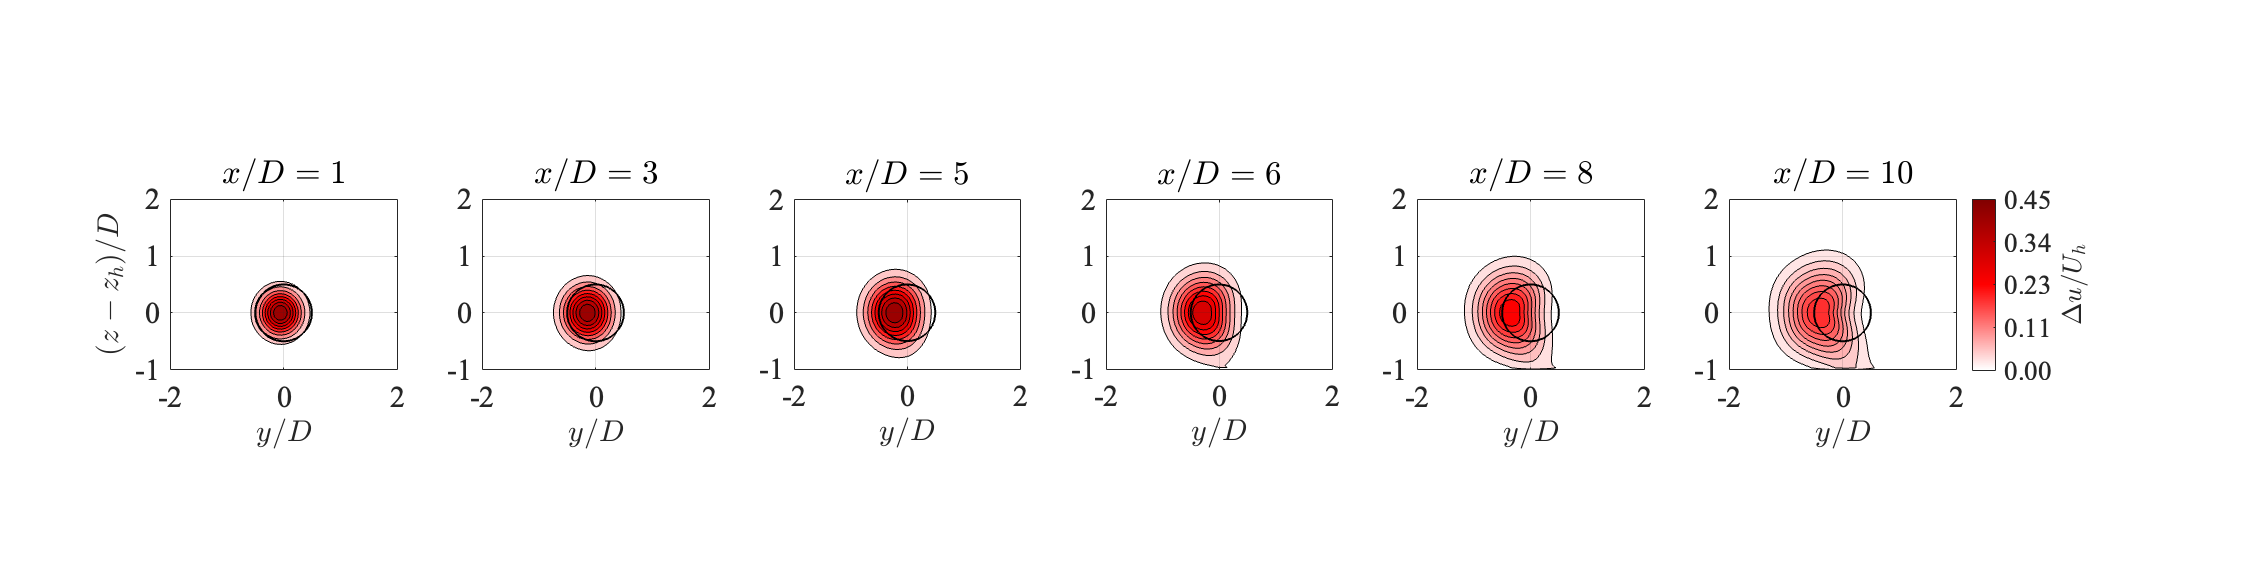

%Plot du_model
set(groot, 'DefaultFigureVisible', 'on');
close all
figure
set(gcf,'Color','w','Units','Centimeters','Position',[10 10 40 10]);
xloc_array=[8:12:70];
[x_circ, y_circ] = computeCircle(0,0, Radius/D, Nx);
counter=1;
for i=xloc_array
    ax=axes;
    ax.Units='Centimeters';
    contourf(y/D,(z-zt)/D,squeeze(du_model(i,:,:))',8,'LineStyle','-');hold on
    plot(x_circ,y_circ,'k','linewidth',1);
    set(ax,'DataAspectratio',[1 1 1]);
    set(ax,'fontsize',15,'fontname','Times');
    colormap(bluewhitered);
    caxis([0 max(Cx)]);
    if counter==numel(xloc_array)
      cb=colorbar;
      cb.Ticks=linspace(0,max(Cx),5);
      cb.Ruler.TickLabelFormat = '%.2f';
      ylabel(cb,'$\Delta u/U_h$','interpreter','latex');
    end
    xlim([-2 2]);
    ylim([-1 2]);
    title(sprintf('$x/D=%0.0f$',x(i)/D),'interpreter','latex');
    
    xlabel('$y/D$','Interpreter','latex','FontSize',15);
    if counter==1
      ylabel('$(z-z_h)/D$','Interpreter','latex','FontSize',15);
    end
    grid on
    ax.Position=[3+(counter-1)*5.5 3 4 4];
    counter=counter+1;
end